# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.5 Stripmap SAR Pulse Repetition Frequency

## Calculate the pulse repetition upper and lower limits

$\frac{2v\;}{D_a }\le \textrm{PRF}\le \frac{c}{2\;R_u }\left(\textrm{Hz}\right)$   Equation (2.21)

% Clear the workspace
clear

% Cross-range resolution (m)
cross_range_resolution = 3.5;

% Unambiguous range (m)
unambiguous_range = 200e3;

% Velocity (m/s)
velocity = linspace(50, 2000, 1e3);

% Antenna azimuth dimension (m)
antenna_width = 2 * cross_range_resolution;

% Calculate the upper limit (Hz)
prf_upper_limit = 299792458 / (2 * unambiguous_range) .* ones(1, length(velocity));

% Calculate the lower limit (Hz)
prf_lower_limit = 2 * velocity / (antenna_width);

## Plot the results

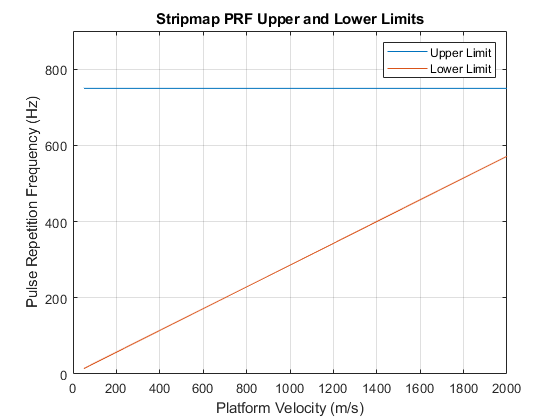

figure;
plot(velocity, prf_upper_limit); hold on
plot(velocity, prf_lower_limit)
xlabel('Platform Velocity (m/s)')
ylabel('Pulse Repetition Frequency (Hz)');
title('Stripmap PRF Upper and Lower Limits');
legend('Upper Limit', 'Lower Limit');
ylim([0, 900]);
yticks([0, 200, 400, 600, 800])
grid on